# ECPE 226 - Homework 03 - Logistic Regression

Implement a logistic regression algorithm. Train said algorithm and test it on "real" handwritten digit data that will give us statistic on how well it performed computational learning.

% Clean up workspace
clear; close all; clc

## PART 1 - MATLAB CODE

% load data
load('usps_modified.mat');

% extract features (Intensity and Symmetry - x1 & x2; and labels - y)
[x, y] = get_features(data);

% add leading zeros to x 
x = [ones(5000, 1) x];

% change y labels to 1->1 everything else->-1
for i=1:5000
    if y(i) ~= 1
        y(i) = -1;
    end
end

% initialize learning rates
nu = [0.1 1 10 50];

% initialize average error array
error_array = NaN(10, 16);

% 4 runs for each learning rate
for j=1:4
    % 10 runs of both algorithms to determine average statistics for each learning rate
    for k=1:10
        
        % initialize training data (400 random samples from data)
        idx = randi([1 5000], 400, 1);
        training_data = [x(idx,:) y(idx)];
        
        % call stochastic logistic regression algorithm N = 400
        [w_stochastic, err_stochastic] = logistic_regression_stochastic(training_data(:, 1:3), training_data(:, 4), nu(j));
        
        % call batch logistic regression N = 400
        [w_batch, err_batch] = logistic_regression_batch(training_data(:, 1:3), training_data(:, 4), nu(j));
        
        % calculate out of sample error
        temperr_stochastic = 0;
        temperr_batch = 0;
        for i=1:5000
            temperr_stochastic = temperr_stochastic + (sign(dot(w_stochastic,x(i,1:3))) ~= y(i));
            temperr_batch = temperr_batch + (sign(dot(w_batch,x(i,1:3))) ~= y(i));
        end
        temperr_stochastic = temperr_stochastic/5000;
        temperr_batch = temperr_batch/5000;
            
        % store error rate for each run of each learning rate
        error_array(k, (j*4)-3:(j*4)) = [err_stochastic temperr_stochastic err_batch temperr_batch];
    end
end

% calculate mean percent error rates
error_rates = mean(error_array)*100;

## PART 2 - PLOTS

    After testing the logistic regression algorithm in the form of batches and stochastic for each learning rate, the error rates were calculated from ten runs. Those error rates can be seen plotted below.

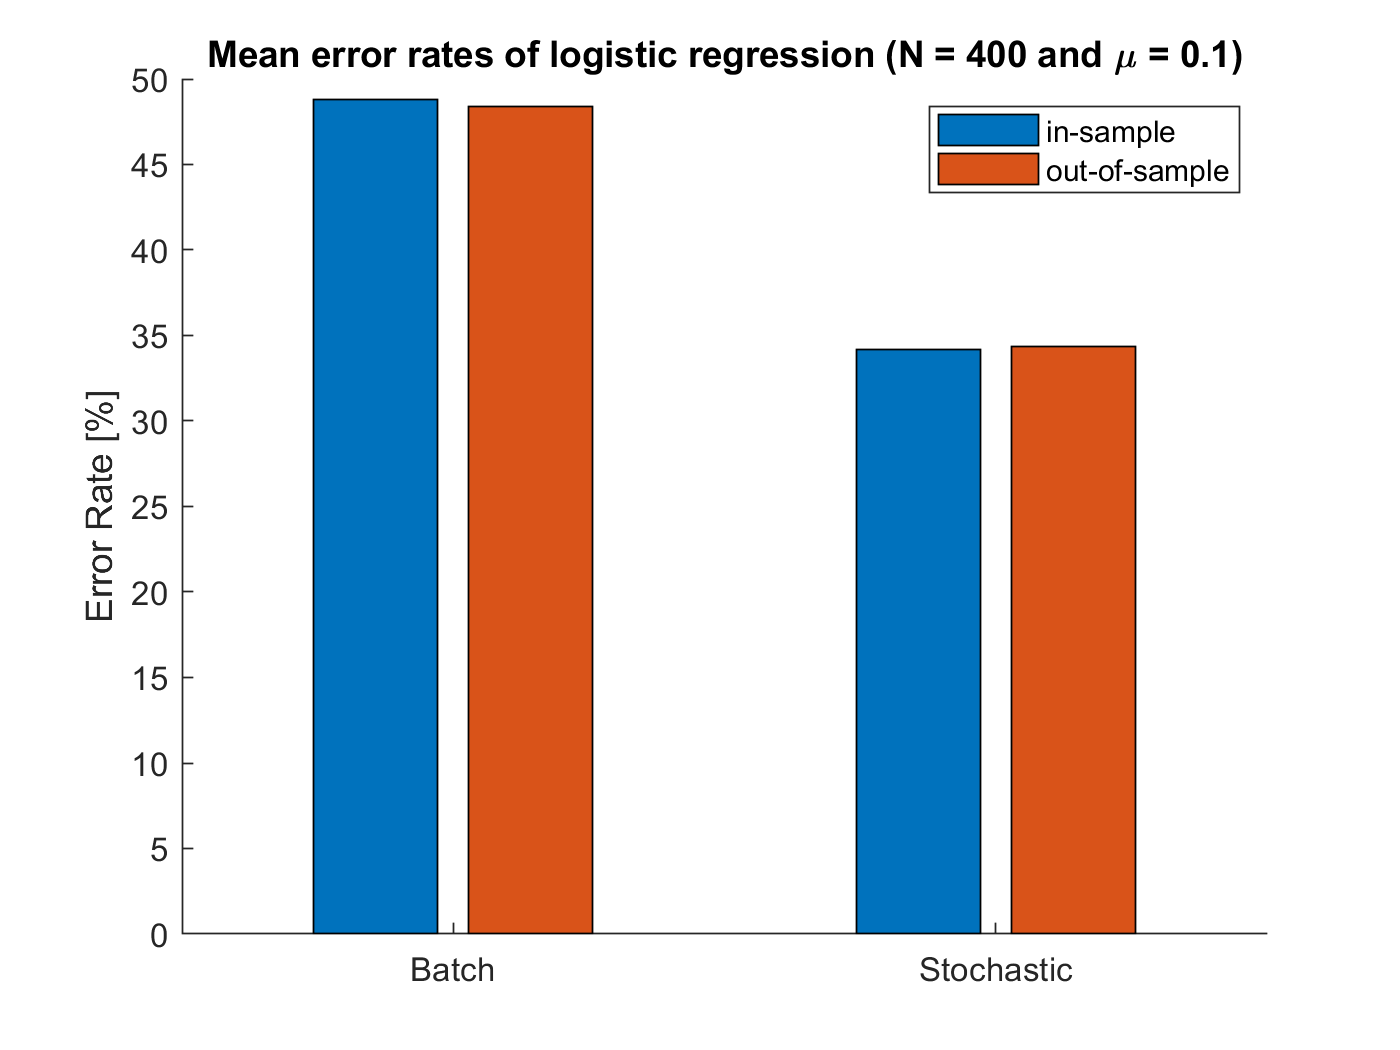

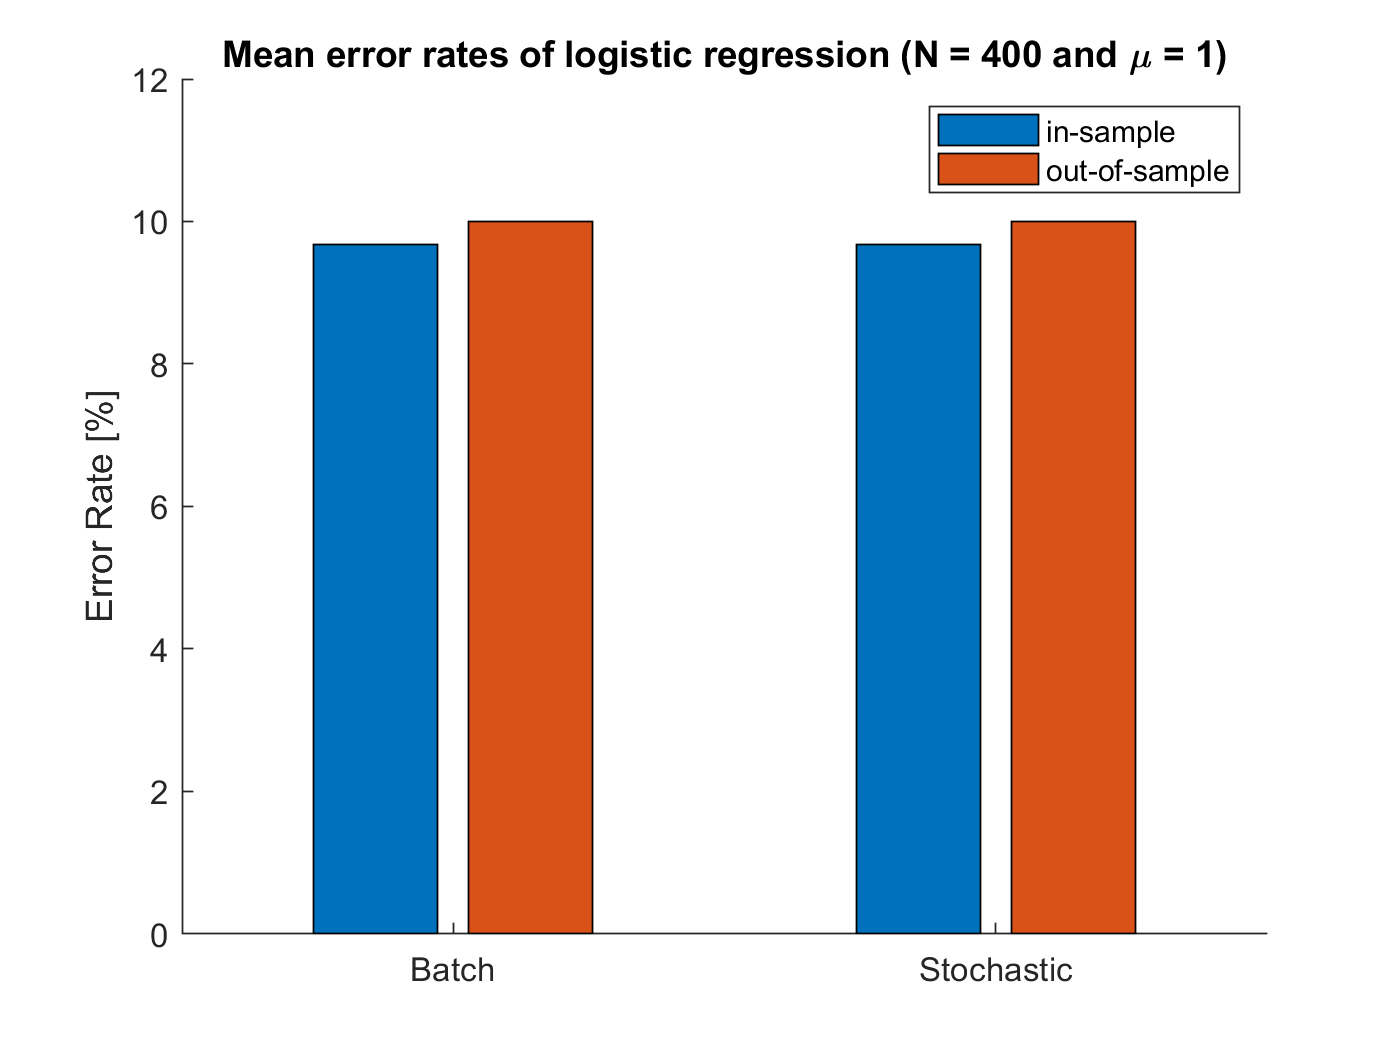

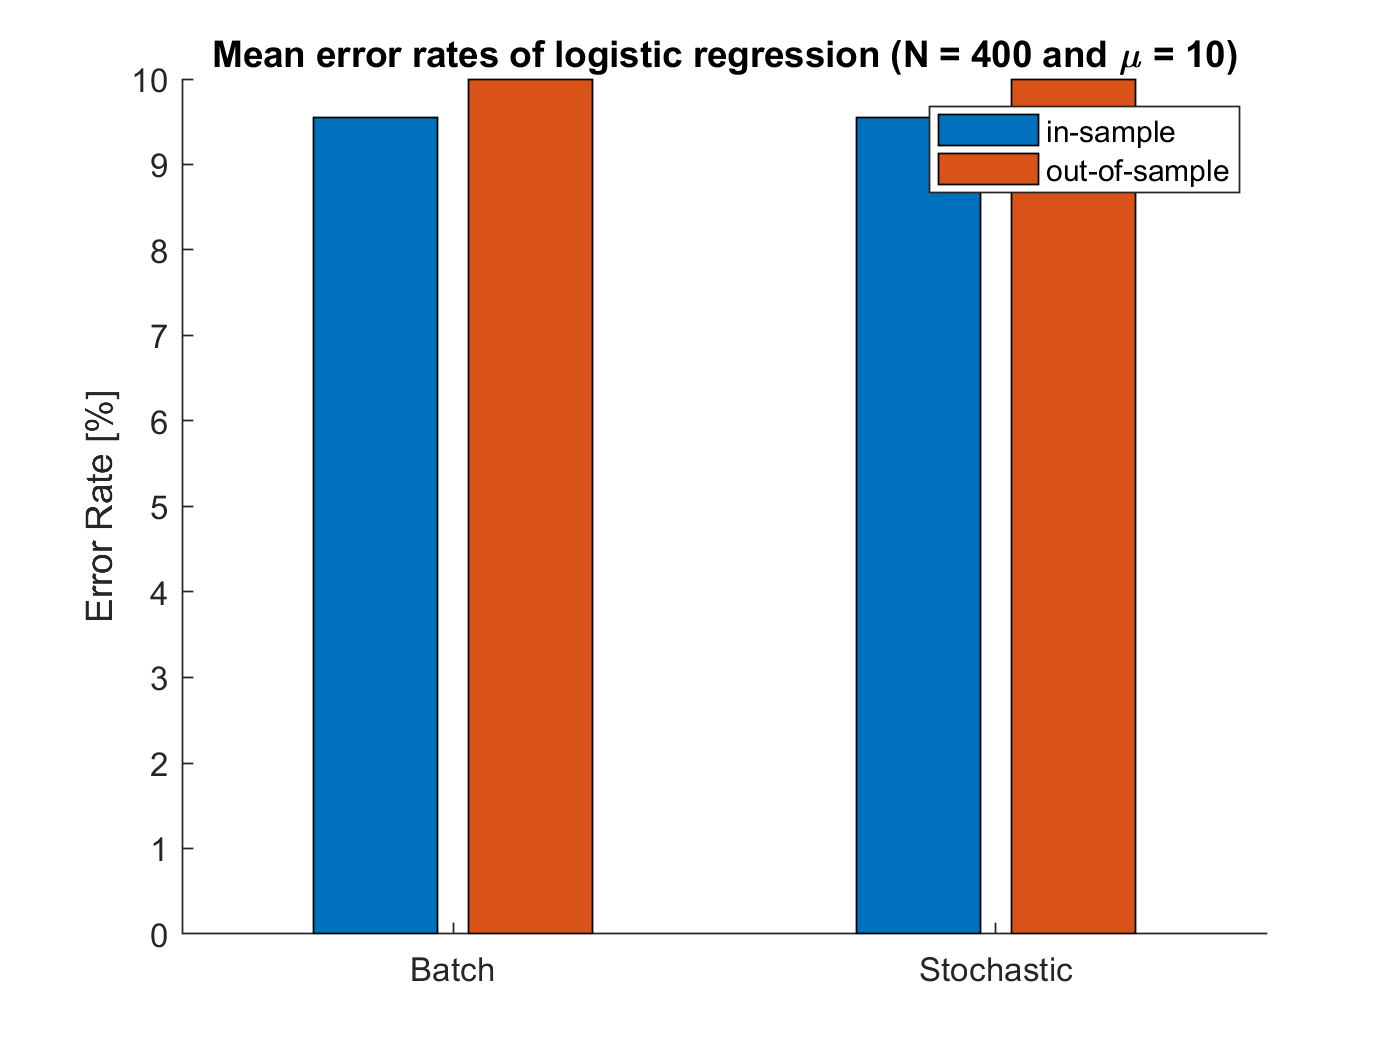

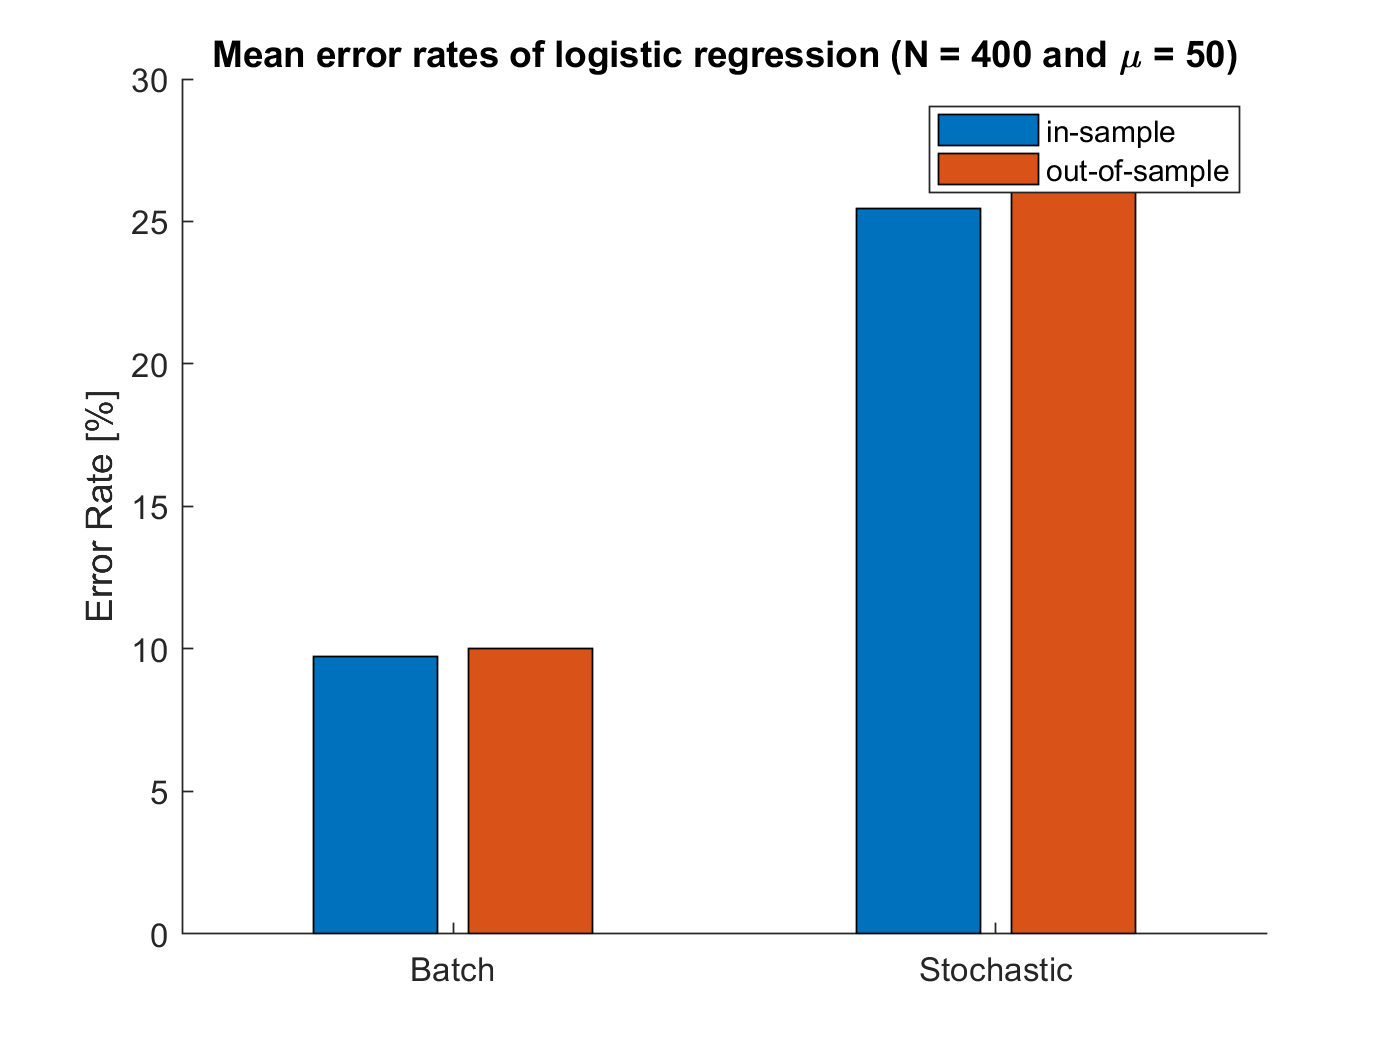

% loop through learning rates
for i=1:4
    
    % Plot bar graph of error rates for N=400
    figure
    hold on
    c = categorical({'Stochastic','Batch'});
    bar(c, [error_rates((i*4)-3), error_rates((i*4)-2); error_rates((i*4)-1), error_rates(i*4)])
    hold on
    title("Mean error rates of logistic regression (N = 400 and \mu = " + num2str(nu(i)) + ")")
    legend('in-sample', 'out-of-sample')
    ylabel("Error Rate [%]")
end

   In terms of stopping criteria, I decided to use the error as I felt it was te more important statistic. When training the data, I wanted to reduce the error rate as low as possible. In order to do that, the algorithm simply checks how much the error has changed and then if it's change is below 1%, it stops. I figure 1% was a good compromise between speed and accuracy. Finally, the learning rate had a significant affect on the error rate and learnin of the algorithm. From the plots, we see that for learning rate of 0.1 and 50 get higher than the 1 and 10 learning rates. This is most likely due to under and over shooting as the algorithm tries to learn too slowly in the 0.1 that it never gets to the minimum and the 50 has it constantly over shooting, never getting to the bottom of the error curve. Whereas 1 and 10 have decent learning rates were the algorithm can learn with reduced learning rates. Also, if running a lower learning rates, it looks like stochastic provides better results and for higher learning rates, the batch provides better results.